clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]


param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


simtime = 10*60;

## Control

% param.ctrl.Ks = control.DesignProcedure1(param,0); 
param.ctrl.Ks = control.DesignProcedure2(param,0,0);

Evaluation of design procedure 2 
Q is positive definite


ans =     0.0016    0.0016    0.0016    0.0150    0.2695    0.2715    0.2718    0.2750    2.7455    3.9375    4.0292    4.1667


Gamma is found to be:


ans = 1.0203

Eigenvalues of the decoupled systems are all negative 


ans =    -4.2846   -2.7730   -0.0498  -31.1007   -4.0327   -0.0204  -35.3673   -3.9953   -0.0204  -29.1618   -3.9953   -0.0195


Eigenvalues of the coupled systems are all negative 


ans =   -82.1771  -71.2049  -56.7517   -6.7556   -3.7411   -4.0336   -3.9960   -3.9961   -0.0497   -0.0195   -0.0204   -0.0204



s = tf('s');
K = blkdiag(param.ctrl.Ks(:,:,1),param.ctrl.Ks(:,:,2),param.ctrl.Ks(:,:,3),param.ctrl.Ks(:,:,4));
M = K * eye(12)/(s * eye(12) - (param.model.A + param.model.B * K * eye(12)) )*param.model.B;

## Structured uncertainties

Defines a logspace to investigate the values over

W = logspace(-1,3,400);

Calculates the singular values of M evaluated at the freqiencies W

SV = sigma(M, W);

Calculates the spectral radius

spectral = zeros(1,length(W));
Ms = freqresp(M,W);
for i=1:length(W)   
    spectral(i) = abs(eigs(Ms(:,:,i),1));
end

Calculates the SSV

[bounds,muinfo]  = mussv(frd(M,W),[4,0],'an');

Points completed: 400/400


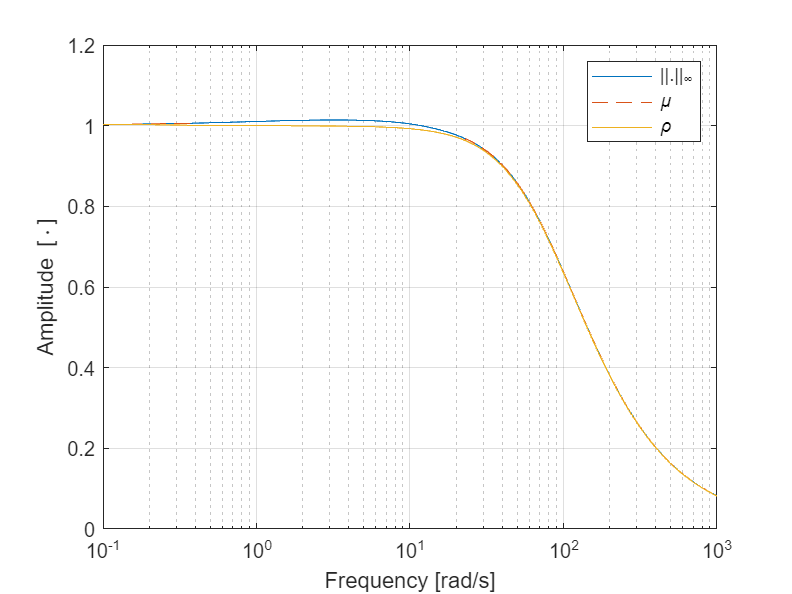

[VDelta,VSigma,VLmi] = mussvextract(muinfo);
upperBound = bounds(1).ResponseData(:);

figure()
semilogx(W,max(SV),W,upperBound,'--',W,spectral)
xlabel("Frequency [rad/s]")
ylabel("Amplitude [\cdot]")
% ylim([0;4])
legend('||.||_\infty', '\mu', '\rho')
grid on

% set(gcf, 'PaperUnits', 'centimeters');
% set(gcf, 'PaperPosition', [0 0 9 9]);
% saveas(gcf,'../Images/Examination_Structure_DP1','epsc')
% saveas(gcf,'../Images/Examination_Structure_DP2','epsc')
% saveas(gcf,'../Images/Examination_Structure_DP2_Unboundgamma','epsc')

## Simulate decoupled system

for i=1:4
    x0 = [param.ctrl.T_wOP(i); param.ctrl.T_aOP(i); 0];
    [t,x] = ode23s(@(t,x)model.decoupledDynamics(t,x,i,param,200),[0 simtime],x0);
    decoupledResults(i).time = t;
    decoupledResults(i).Tw = x(:,1);
    decoupledResults(i).Ta = x(:,2);
    decoupledResults(i).T = x(:,3);
end

## Simulate coupled system

x0 = [param.ctrl.T_wOP.'; param.ctrl.T_aOP.'; zeros(4,1)];
[t,x] = ode23s(@(t,x)model.coupledDynamics(t,x,param,200),[0 simtime],x0);

0.000000, -0.000000, -0.188544, -0.188544, 
0.000000, 0.000000, -0.297559, -0.000000, 
-0.259263, 0.000000, 0.000000, 0.000000, 


coupledResults.time = t;
coupledResults.Tw = x(:,1:4);
coupledResults.Ta = x(:,5:8);
coupledResults.T = x(:,9:12);

## Plot simulation results

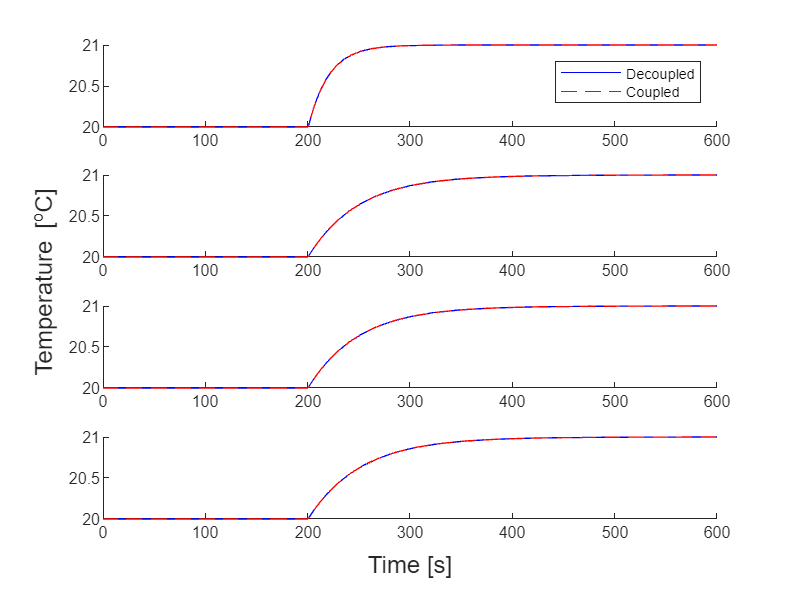

figure()
f = tiledlayout('vertical');
for i=1:4
    nexttile
    hold on
    plot(decoupledResults(i).time,decoupledResults(i).Ta-273.15,'blue')
    plot(coupledResults.time,coupledResults.Ta(:,i)-273.15,['red','--'])
    if i==1
        legend('Decoupled','Coupled',Location='northeast')
    end
    hold off
end
xlabel(f,'Time [s]')
ylabel(f,'Temperature [^{o}C]')
saveas(gcf,'../Images/Examination_Structure_DP2_Unboundgamma_step','epsc')